%计算每月21号到春分的天数D
d = 21;
m = 0:1:11;
A = [31,28,31,30,31,30,31,31,30,31,30,31];
D = cumsum(A)+d;
D = D-D(3);
%当地时间ST
ST=9:1.5:15

ST =     9.0000   10.5000   12.0000   13.5000   15.0000


%太阳时角omega
omega=pi/12*(ST-12)

omega =    -0.7854   -0.3927         0    0.3927    0.7854


%太阳赤纬角delta的正余弦值（每天不同，12个值）
sin_delta = sin(2*pi*D/365)*sin(2*pi/360*23.45)

sin_delta =    -0.3382   -0.2024         0    0.1965    0.3452    0.3979    0.3435    0.1935   -0.0034   -0.2054   -0.3469   -0.3979


cos_delta = sqrt(1-sin_delta.^2)

cos_delta =     0.9411    0.9793    1.0000    0.9805    0.9385    0.9174    0.9392    0.9811    1.0000    0.9787    0.9379    0.9174


%当地纬度phi
phi = 39.4*pi/180;
%海拔高度H(km)
H = 3;
%太阳高度角alpha_s的正余弦值（每天每时不同，60个值）
sin_alpha_s = cos_delta'*cos(omega)*cos(phi)+sin_delta'*sin(phi)%12*5
cos_alpha_s = sqrt(1-sin_alpha_s.^2);%12*5

sin_alpha_s =     0.2996    0.4572    0.5125    0.4572    0.2996
    0.4066    0.5706    0.6283    0.5706    0.4066
    0.5464    0.7139    0.7727    0.7139    0.5464
    0.6605    0.8247    0.8824    0.8247    0.6605
    0.7319    0.8891    0.9443    0.8891    0.7319
    0.7539    0.9075    0.9615    0.9075    0.7539
    0.7312    0.8885    0.9437    0.8885    0.7312
    0.6589    0.8232    0.8810    0.8232    0.6589
    0.5442    0.7117    0.7706    0.7117    0.5442
    0.4044    0.5683    0.6259    0.5683    0.4044


%太阳方位角gamma_s的正余弦值（每天每时不同，60个值）
cos_gamma_s = (sin_delta'-sin_alpha_s*sin(phi))./(cos_alpha_s*cos(phi))%12*5
cos_gamma_s = cos_gamma_s';
cos_gamma_s = cos_gamma_s(:)%60*1
sin_gamma_s = -cos_delta'*sin(omega)./cos_alpha_s
sin_gamma_s = sin_gamma_s';
sin_gamma_s = sin_gamma_s(:);


cos_gamma_s =    -0.7166   -0.9143   -1.0000   -0.9143   -0.7166
   -0.6523   -0.8898   -1.0000   -0.8898   -0.6523
   -0.5359   -0.8375   -1.0000   -0.8375   -0.5359
   -0.3839   -0.7482   -1.0000   -0.7482   -0.3839
   -0.2267   -0.6197   -1.0000   -0.6197   -0.2267
   -0.1587   -0.5488   -1.0000   -0.5488   -0.1587
   -0.2288   -0.6218   -1.0000   -0.6218   -0.2288
   -0.3866   -0.7501   -1.0000   -0.7501   -0.3866
   -0.5381   -0.8386   -1.0000   -0.8386   -0.5381
   -0.6538   -0.8904   -1.0000   -0.8904   -0.6538


cos_gamma_s =    -0.7166
   -0.9143
   -1.0000
   -0.9143
   -0.7166
   -0.6523
   -0.8898
   -1.0000
   -0.8898
   -0.6523



%将太阳高度角的正余弦值转为一列向量
sin_alpha_s = sin_alpha_s';
sin_alpha_s = sin_alpha_s(:) %每天每个时间点的数值（60*1）

sin_alpha_s =     0.2996
    0.4572
    0.5125
    0.4572
    0.2996
    0.4066
    0.5706
    0.6283
    0.5706
    0.4066


cos_alpha_s = cos_alpha_s';
cos_alpha_s = cos_alpha_s(:) %60*1

cos_alpha_s =     0.9541
    0.8894
    0.8587
    0.8894
    0.9541
    0.9136
    0.8212
    0.7780
    0.8212
    0.9136


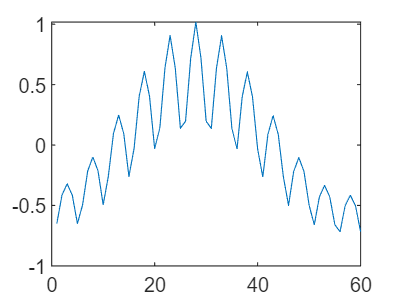


sss=acos(cos_alpha_s)-cos_alpha_s;
plot(sss)

%太阳常数G0(kW/m^2)
G0 = 1.366

G0 = 1.3660

%法向直接辐射辐照度DNI
a = 0.4237-0.00821*(6-H)^2

a = 0.3498

b = 0.5055+0.00595*(6.5-H)^2

b = 0.5784

c = 0.2711+0.01858*(2.5-H)^2

c = 0.2757

DNI = G0*(a+b*exp(-c./sin_alpha_s))

DNI =     0.7925
    0.9101
    0.9392
    0.9101
    0.7925
    0.8788
    0.9652
    0.9872
    0.9652
    0.8788


DNI = reshape(DNI,5,12)

DNI =     0.7925    0.8788    0.9548    0.9983    1.0199    1.0259    1.0197    0.9977    0.9539    0.8774    0.7854    0.7386
    0.9101    0.9652    1.0148    1.0434    1.0572    1.0609    1.0571    1.0430    1.0141    0.9642    0.9056    0.8760
    0.9392    0.9872    1.0308    1.0559    1.0678    1.0709    1.0677    1.0556    1.0302    0.9864    0.9353    0.9096
    0.9101    0.9652    1.0148    1.0434    1.0572    1.0609    1.0571    1.0430    1.0141    0.9642    0.9056    0.8760
    0.7925    0.8788    0.9548    0.9983    1.0199    1.0259    1.0197    0.9977    0.9539    0.8774    0.7854    0.7386


mean_DNI = mean(DNI)'

mean_DNI =     0.8689
    0.9350
    0.9940
    1.0278
    1.0444
    1.0489
    1.0443
    1.0274
    0.9933
    0.9339



%定日镜宽度和高度(m)
mirror_width = 8

mirror_width = 8

mirror_height = 8

mirror_height = 8

%定日镜面积(m^2)
A = mirror_width*mirror_height

A = 64

%定日镜安装高度(m)
h1 = 6

h1 = 6

%吸收塔高度(m)
h2 = 80

h2 = 80

%定日镜总数N(面)
N = 1745;
%定日镜坐标xy
xy_1 = xlsread('附件.xlsx')

xy_1 =   107.2500   11.6640
  105.3600   23.1910
  102.2350   34.4470
   97.9110   45.2990
   92.4400   55.6190
   85.8840   65.2880
   78.3220   74.1910
   69.8410   82.2240
   60.5420   89.2930
   50.5330   95.3150


%镜面中心到集热器中心的距离d_HR(m)
d_HR = sqrt(xy_1(:,1).^2+xy_1(:,2).^2+(h1-h2)^2)

d_HR =   130.8228
  130.8226
  130.8227
  130.8226
  130.8229
  130.8227
  130.8229
  130.8226
  130.8227
  130.8225


%大气透射率(其中d_HR<=1000)
eta_at =  0.99321-0.0001176*d_HR+1.97*1e-8*d_HR.^2

eta_at =     0.9782
    0.9782
    0.9782
    0.9782
    0.9782
    0.9782
    0.9782
    0.9782
    0.9782
    0.9782


%镜面反射率eta_ref
eta_ref = 0.92

eta_ref = 0.9200


%反射光向量
reflect = ([0,0,h2]-[xy_1,h1*ones(N,1)]);
norm = sqrt(reflect(:,1).^2+reflect(:,2).^2+reflect(:,3).^2);
reflect = reflect./norm

reflect =    -0.8198   -0.0892    0.5657
   -0.8054   -0.1773    0.5657
   -0.7815   -0.2633    0.5657
   -0.7484   -0.3463    0.5657
   -0.7066   -0.4251    0.5657
   -0.6565   -0.4991    0.5657
   -0.5987   -0.5671    0.5657
   -0.5339   -0.6285    0.5657
   -0.4628   -0.6825    0.5657
   -0.3863   -0.7286    0.5657


%入射光方向向量
incident = [cos_alpha_s.*sin_gamma_s,cos_alpha_s.*cos_gamma_s,sin_alpha_s]

incident =    0.6654 + 0.0000i  -0.6837 + 0.0000i   0.2996 + 0.0000i
   0.3601 + 0.0000i  -0.8132 + 0.0000i   0.4572 + 0.0000i
   0.0000 + 0.0000i  -0.8587 + 0.0000i   0.5125 + 0.0000i
   0.3601 + 0.0000i  -0.8132 + 0.0000i   0.4572 + 0.0000i
   0.6654 + 0.0000i  -0.6837 + 0.0000i   0.2996 + 0.0000i
   0.6925 + 0.0000i  -0.5960 + 0.0000i   0.4066 + 0.0000i
   0.3748 + 0.0000i  -0.7307 + 0.0000i   0.5706 + 0.0000i
   0.0000 + 0.0000i  -0.7780 + 0.0000i   0.6283 + 0.0000i
   0.3748 + 0.0000i  -0.7307 + 0.0000i   0.5706 + 0.0000i
   0.6925 + 0.0000i  -0.5960 + 0.0000i   0.4066 + 0.0000i


%余弦效率
cos_eff = zeros(N,60);
for i = 1:60
    temp = sum(reflect.*incident(i,:),2);
    cos_eff(:,i) = sqrt((1+temp)/2);
end
cos_eff_all = real(cos_eff)

cos_eff_all =     0.5852    0.7197    0.8266    0.7197    0.5852    0.5981    0.7351    0.8440    0.7351    0.5981    0.6202    0.7558    0.8642    0.7558    0.6202    0.6446    0.7735    0.8778    0.7735    0.6446    0.6647    0.7854    0.8842    0.7854    0.6647    0.6723    0.7893    0.8855    0.7893    0.6723    0.6645    0.7853    0.8841    0.7853    0.6645    0.6442    0.7733    0.8776    0.7733    0.6442    0.6198    0.7554    0.8639    0.7554    0.6198    0.5978    0.7348    0.8437    0.7348    0.5978
    0.6143    0.7459    0.8492    0.7459    0.6143    0.6237    0.7585    0.8641    0.7585    0.6237    0.6400    0.7745    0.8802    0.7745    0.6400    0.6581    0.7872    0.8895    0.7872    0.6581    0.6734    0.7950    0.8923    0.7950    0.6734    0.6791    0.7973    0.8924    0.7973    0.6791    0.6732    0.7949    0.8923    0.7949    0.6732    0.6579    0.7870    0.8894    0.7870    0.6579    0.6397    0.7742    0.8800    0.7742    0.6397    0.6235    0.7582    0.8638    0

cos_eff = mean(reshape(mean(cos_eff),5,12));%每月21日的平均余弦效率
cos_eff = real(cos_eff);
cos_eff_mean = mean(cos_eff);%年平均余弦效率

%阴影遮挡效率
eta_sb = 1;
%集热器截断效率
eta_trunc = 0.925;
%定日镜的光学效率eta
eta_all = real(eta_sb*cos_eff_all.*eta_at*eta_trunc*eta_ref)%1745*60

eta_all =     0.4871    0.5991    0.6881    0.5991    0.4871    0.4979    0.6119    0.7026    0.6119    0.4979    0.5163    0.6291    0.7194    0.6291    0.5163    0.5365    0.6439    0.7307    0.6439    0.5365    0.5533    0.6538    0.7360    0.6538    0.5533    0.5596    0.6571    0.7371    0.6571    0.5596    0.5531    0.6537    0.7359    0.6537    0.5531    0.5362    0.6437    0.7306    0.6437    0.5362    0.5160    0.6288    0.7191    0.6288    0.5160    0.4976    0.6116    0.7023    0.6116    0.4976
    0.5113    0.6209    0.7069    0.6209    0.5113    0.5192    0.6313    0.7193    0.6313    0.5192    0.5327    0.6447    0.7327    0.6447    0.5327    0.5479    0.6553    0.7405    0.6553    0.5479    0.5605    0.6617    0.7428    0.6617    0.5605    0.5653    0.6637    0.7428    0.6637    0.5653    0.5604    0.6617    0.7428    0.6617    0.5604    0.5476    0.6551    0.7404    0.6551    0.5476    0.5325    0.6445    0.7325    0.6445    0.5325    0.5190    0.6311    0.7190    0.631

eta = mean(eta_all)%1*60

eta =     0.5761    0.5974    0.6047    0.5974    0.5761    0.5906    0.6124    0.6200    0.6124    0.5906    0.6092    0.6311    0.6387    0.6311    0.6092    0.6242    0.6453    0.6526    0.6453    0.6242    0.6334    0.6534    0.6603    0.6534    0.6334    0.6362    0.6557    0.6625    0.6557    0.6362    0.6333    0.6533    0.6603    0.6533    0.6333    0.6240    0.6451    0.6524    0.6451    0.6240    0.6089    0.6308    0.6384    0.6308    0.6089    0.5903    0.6121    0.6197    0.6121    0.5903


eta = mean(reshape(eta,5,12))'%12*1

eta =     0.5903
    0.6052
    0.6239
    0.6383
    0.6468
    0.6493
    0.6467
    0.6381
    0.6236
    0.6049


%定日镜场的输出热功率E_field
E_field = mean(N*mirror_height*mirror_width*mean_DNI.*eta)/1000

E_field = 67.1786

%单位面积镜面平均输出热功率
P = mean_DNI.*eta

P =     0.5129
    0.5659
    0.6201
    0.6561
    0.6755
    0.6810
    0.6754
    0.6556
    0.6194
    0.5649


P_mean = mean(P)

P_mean = 0.6015